% 1 
% 2D

syms p q t

M=[p t;
    t q]

$$M = \left(\begin{array}{cc} p & t\\ t & q \end{array}\right)$$


m=M^-1

$$m = \left(\begin{array}{cc} \frac{q}{p\,q-t^{2}} & -\frac{t}{p\,q-t^{2}}\\ -\frac{t}{p\,q-t^{2}} & \frac{p}{p\,q-t^{2}} \end{array}\right)$$

l1=1;
l2=1;
m1=1;
m2=1;
g=1;

t1_init=0.5*pi;
t2_init=1*pi;
dt1_init=0;
dt2_init=2;

tspan=[0 80];
% tspan=linspace(0,5,51);
% tspan=0:.05:5;
init=[t1_init;t2_init;dt1_init;dt2_init];

p=(m1/m2+1)*l1/l2;
q=l2/l1;
lm=(l1+l2);
p1=(m1/m2+1)*g/l2;
p2=g/l1;

func=@(t,x)[x(3);x(4);1/(p*q-cos(x(2)-x(1))^2)*...
    [q -cos(x(2)-x(1));-cos(x(2)-x(1)) p]*...
    [sin(x(2)-x(1))*x(4)^2+p1*sin(x(1));-sin(x(2)-x(1))*x(3)^2+p2*sin(x(2))]];

[T,Y]=ode45(func,tspan,init);

theta1=Y(:,1);
theta2=Y(:,2);

x1=l1*sin(theta1);
y1=l1*cos(theta1);
x2=x1+l2*sin(theta2);
y2=y1+l2*cos(theta2);

figure();
hold on;

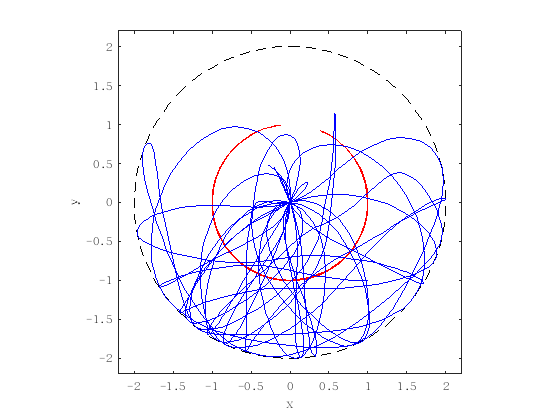


ang=linspace(0,2*pi,100);
plot(lm*sin(ang),lm*cos(ang),'k--');

plot(x1,y1,'r');
plot(x2,y2,'b');

% plot([x1*0 x1]',[y1*0 y1]','r','linewidth',.5);
% plot([x1 x2]',[y1 y2]','b','linewidth',.5);

hold off;


axis(1.1*[-lm lm -lm lm]);
axis square;
box on;
xlabel('x');ylabel('y');

% % 3D
% 
% syms t l1 theta1(t) phi1(t) l2 theta2(t) phi2(t) m1 m2 Dt1(t) Dt2(t) Dp1(t) Dp2(t) D2t1(t) D2t2(t) D2p1(t) D2p2(t)
% 
% assume(l1 > 0);
% assume(l2 > 0);
% assume(m1 > 0);
% assume(m2 > 0);
% 
% r1=l1*[sin(theta1)*cos(phi1);sin(theta1)*sin(phi1);cos(theta1)];
% r12=l2*[sin(theta2)*cos(phi2);sin(theta2)*sin(phi2);cos(theta2)];
% r2=r1+r12;
% 
% dr1=diff(r1,t,1);
% dr2=diff(r2,t,1);
% 
% L1=sum(dr1.^2);
% L2=sum(dr2.^2);
% 
% L=1/2*m1*L1+1/2*m2*L2;
% LL=subs(L,[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)],[Dt1,Dp1,Dt2,Dp2]);
% 
% DLL1={functionalDerivative(LL,theta1);
%     functionalDerivative(LL,phi1);
%     functionalDerivative(LL,theta2);
%     functionalDerivative(LL,phi2)};
% DLL2={functionalDerivative(LL,Dt1);
%     functionalDerivative(LL,Dp1);
%     functionalDerivative(LL,Dt2);
%     functionalDerivative(LL,Dp2)};
% DLL3={subs(DLL1{1},[Dt1,Dp1,Dt2,Dp2],[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)]);
%     subs(DLL1{2},[Dt1,Dp1,Dt2,Dp2],[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)]);
%     subs(DLL1{3},[Dt1,Dp1,Dt2,Dp2],[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)]);
%     subs(DLL1{4},[Dt1,Dp1,Dt2,Dp2],[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)])};
% DLL4={subs(DLL2{1},[Dt1,Dp1,Dt2,Dp2],[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)]);
%     subs(DLL2{2},[Dt1,Dp1,Dt2,Dp2],[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)]);
%     subs(DLL2{3},[Dt1,Dp1,Dt2,Dp2],[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)]);
%     subs(DLL2{4},[Dt1,Dp1,Dt2,Dp2],[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)])};
% DLL5=diff(DLL4,t,1);
% 
% EQU=(DLL3==DLL5);
% % simplify(EQU,10)
% 
% SEQ=simplify(EQU,10);
% SEQ1=subs(SEQ,[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t),...
%     diff(theta1,t,2),diff(phi1,t,2),diff(theta2,t,2),diff(phi2,t,2)],...
%     [Dt1,Dp1,Dt2,Dp2,D2t1,D2p1,D2t2,D2p2])


% % 3D
% 
% syms t l1 theta1(t) phi1(t) l2 theta2(t) phi2(t) m1 m2 Dt1(t) Dt2(t) Dp1(t) Dp2(t) D2t1(t) D2t2(t) D2p1(t) D2p2(t)
% 
% assume(l1 > 0);
% assume(l2 > 0);
% assume(m1 > 0);
% assume(m2 > 0);
% 
% r1=[sin(theta1)*cos(phi1);sin(theta1)*sin(phi1);cos(theta1)];
% r12=[sin(theta2)*cos(phi2);sin(theta2)*sin(phi2);cos(theta2)];
% % r2=r1+r12;
% 
% dr1=diff(r1,t,1);
% dr12=diff(r12,t,1);
% 
% L1=sum(dr1.^2);
% L2=sum(dr12.^2);
% L3=sum(dr12.*dr1);
% 
% LL3=subs(L3,[diff(theta1,t),diff(phi1,t),diff(theta2,t),diff(phi2,t)],[Dt1,Dp1,Dt2,Dp2]);
% expand(LL3)


% syms x1 y1 l1 x2 y2 l2
% a=l1^2/x1^2;
% b=l1^2/y1^2;
% c=1/(1-1/a-1/b);
% d=l2^2/x2^2;
% e=l2^2/y2^2;
% f=1/(1-1/d-1/e);
% A=[ones(3,3) zeros(3,3);zeros(3,3),ones(3,3)]-diag([a b c d e f])
% R=rref(A)
% rank(A)

% 3D

l1=1;
l2=1;
m1=1;
m2=1;
g=1;

x1_init=0*l1;
y1_init=0*l1;
z1_init=-sqrt(l1^2-x1_init^2-y1_init^2);
x2_init=1*l2;
y2_init=0*l2;
z2_init=sqrt(l2^2-x2_init^2-y2_init^2);

dx1_init=0;
dy1_init=0;
dz1_init=0;
dx2_init=0;
dy2_init=1;
dz2_init=0;

tspan=[0 20];
% tspan=linspace(0,5,51);
% tspan=0:.05:5;
init=[x1_init;y1_init;z1_init;x2_init;y2_init;z2_init;...
    dx1_init;dy1_init;dz1_init;dx2_init;dy2_init;dz2_init;0;0];

p=(m1/m2+1);
lm=l1+l2;

func3DD=@(t,x)func3D(t,x,p,g);
[T,Y]=ode45(func3DD,tspan,init);

函数或变量 'func3D' 无法识别。
出错 untitled (第 178 行)
func3DD=@(t,x)func3D(t,x,p,g);
出错 odearguments (第 90 行)
f0 = feval(ode,t0,y0,args{:});   % ODE15I sets args{1} to yp0.
出错 ode45 (第 115 行)
  odearguments(FcnHandlesUsed, solver_name, ode, tsp


x1=Y(:,1);
y1=Y(:,2);
z1=Y(:,3);
x2=Y(:,1)+Y(:,4);
y2=Y(:,2)+Y(:,5);
z2=Y(:,3)+Y(:,6);

figure();
hold on;

plot3(x1,y1,z1,'r');
plot3(x2,y2,z2,'b');

% plot3([x1*0 x1]',[y1*0 y1]',[z1*0 z1]','r','linewidth',.5);
% plot3([x1 x2]',[y1 y2]',[z1 z2]','b','linewidth',.5);

hold off;


axis(1.1*[-lm lm -lm lm -lm lm]);
axis square;
box on;
view(3);
xlabel('x');ylabel('y');zlabel('z');



% function [y] = func3D(t,x,p,g)
% r1=[x(1);x(2);x(3)];
% r2=[x(4);x(5);x(6)];
% dr1=[x(7);x(8);x(9)];
% dr2=[x(10);x(11);x(12)];
% lmb1=x(13);
% lmb2=x(14);
% 
% A11=[p*eye(3) eye(3);
%     eye(3) eye(3)];
% A12=-[r1 zeros(3,1);zeros(3,1) r2];
% A=[A11 A12;-A12' zeros(2,2)];
% B=-[0;0;g*p;0;0;g;sum(dr1.^2);sum(dr2.^2)];
% 
% y=zeros(14,1);
% y(1:6)=x(7:12);
% y(7:14)=A^(-1)*B;
% end


% 2

syms a t x
y=(4*pi*a^2*t)^(-1/2)*exp(-x^2/4/a/a/t ...
    );
dy1=simplify(a^2*diff(y,x,2))

$$dy1 = -\frac{{\mathrm{e}}^{-\frac{x^{2}}{4\,a^{2}\,t}}\,\left(2\,a^{2}\,t-x^{2}\right)}{8\,t\,\sqrt{\pi }\,{\left(a^{2}\,t\right)}^{3/2}}$$

dy2=simplify(diff(y,t,1))

$$dy2 = -\frac{{\mathrm{e}}^{-\frac{x^{2}}{4\,a^{2}\,t}}\,\left(2\,a^{2}\,t-x^{2}\right)}{8\,t\,\sqrt{\pi }\,{\left(a^{2}\,t\right)}^{3/2}}$$

simplify(dy1-dy2)

$$ans = 0$$

a=1;
L=10;
t1=1;
H=10.^(-2:.1:0);
% DT=.004:.001:.006;
DT=10.^(-4:.2:0);

N1=length(H);
N2=length(DT);
ERR=zeros(N1,N2);

for ii=1:N1
    for jj=1:N2
        h=H(ii);
        dt=DT(jj);
        
        x=h*(-floor(L/2/h):floor(L/2/h));
        N=length(x);
        ut=(4*pi*a^2*t1)^(-1/2)*exp(-x'.^2/4/a/a/t1);
        u=zeros(N,1);
        u(N/2+.5)=1/h;
        % u=(4*pi*a^2*t0)^(-1/2)*exp(-x'.^2/4/a/a/t0);
        % plot(x,u);
        
        M0=-2*eye(N)+diag(ones(1,N-1),1)+diag(ones(1,N-1),-1);
        M=eye(N)+a^2/h^2*dt*M0;
        u=M^floor(t1/dt)*u;
        
        ERR(ii,jj)=sum((u-ut).^2)/N;
%         figure();
%         hold on;
%         plot(x,u,'linewidth',2);
%         plot(x,ut,'--','linewidth',2);
%         hold off
%         legend('calculated','theoretical')
%         box on;
    end
end

% plot(H,diag(ERR))

[HH,DDTT]=meshgrid(H,DT);
figure();
hold on;
pcolor(log10(HH'),log10(DDTT'),log10(ERR));
shading flat;
colorbar;
plot(log10(H),log10(2*H.^2/a^2),'k--','linewidth',2);
plot(log10(H),log10(.1*2*H.^2/a^2),'w--','linewidth',2);
axis([-2 0 -4 0])
set(gca,'layer','top')
xlabel('log10(h)');ylabel('log10(dt)');
